# End-to-End Weather Analytics & Forecasting (Delhi Climate - Kaggle Data)

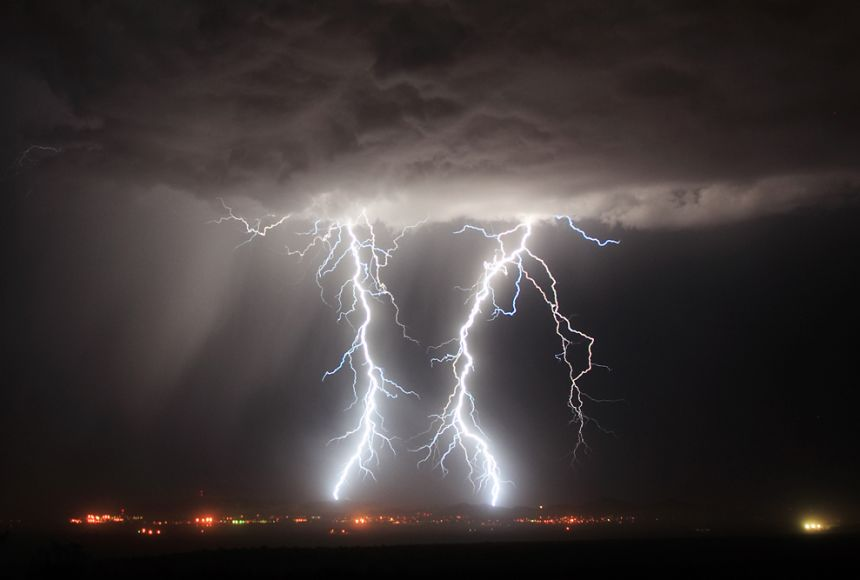   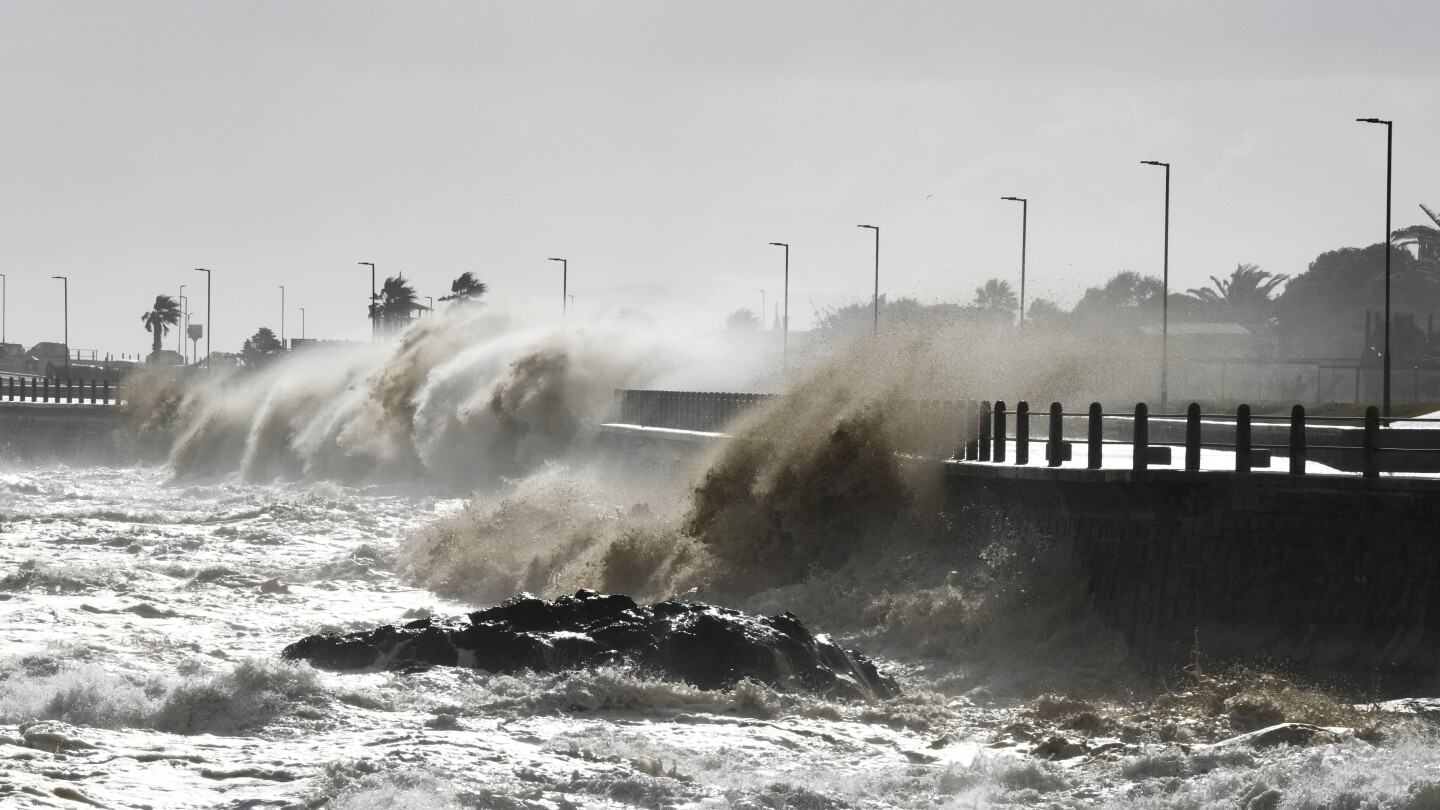

## Introduction

In this demo, we will walk through a complete **end-to-end workflow for weather data analytics and forecasting using MATLAB**. The goal is to demonstrate how data can be taken from its raw form, cleaned, explored, visualized for insights, modeled with machine learning and forecasting tools, and finally how the workflow can be scaled up for deployment.

The dataset that we'll use comes from **Kaggle**'s [**Daily Climate Time Series Data for Delhi**](https://www.kaggle.com/datasets/selfishgene/historical-hourly-weather-data?resource=download). It contains daily records of mean temperature, humidity, wind speed, pressure, wind direction, city attributes and weather descriptions. This dataset is a good fit for this demo because it has a long historical span, is representative of real-world weather time series, and requires manageable preprocessing steps.

The flow of the script follows a structured pipeline:

- **Data importing** - Read in Kaggle dataset and standardise its format

- **Exploration** - Summarize and inspect data, check for missing values, and get a sense of its structure

- **Preprocessing** - Clean the data, handle missing entries, and engineer features such as rolling averages and lag variables

- **Visualization** - Plot trends, seasonal cycles, and correlations to extract insights, and provide geographical context with the Mapping Toolbox

- **Modelling** - Use the **Regression Learner App** to build supervised ML models for predicting temperature/

- **Forecasting** - Apply time-series forecasting techniques, including **Econometric Modeler (ARIMA)** to predict future climate conditions

- **Deployment**

By the end of this demo, you'll see how MATLAB provides a seamless workflow for going from raw data to insights, models, forecasts and deployment, all withing a single environment.

clear; clc; close all;

## 1. Data Import

### Read data using the data import tool

% Import data by double clicking on file and using the import selection
% "Generate Function" tweatho generate a function for importing the dataset.

% Use functions to read each dataset
% city_attributes = importCityAttributes("data/city_attributes.csv");
% humidity = importHumidity("data/humidity.csv");
% pressure = importPressure("data/pressure.csv");
% temperature = importTemperature("data/temperature.csv");
% weather_description = importWeatherDescription("weather_description.csv");
% wind_direction = importWindDirection("data/wind_direction.csv");
% wind_speed = importWindSpeed("data/wind_speed.csv");

### Read data using the readtable function

% Create array of data csv files
dataFiles = ["city_attributes.csv", "humidity.csv", "pressure.csv", ...
    "temperature.csv", "weather_description.csv", "wind_direction.csv", ...
    "wind_speed.csv"];

% Read all datasets into a structured format
dataStruct = readData(dataFiles);

function dataStruct = readData(dataFiles)
    dataStruct = struct();

    for idx = 1:numel(dataFiles)
        dataFile = dataFiles(idx);
        filePath = fullfile("data/", dataFile);
        tableName = extractBefore(dataFile, ".csv");
        warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
        data = readtable(filePath);
        dataStruct.(tableName) = data;
    end
end

## 2. Data Exploration and Preprocessing

### Select Attributes, Filter Dates and Combine Data

combinedData = [];
vars = {'humidity', 'temperature'};

startDate = datetime('2017-06-01');
endDate = datetime("2017-06-30");

for idx = 1:numel(vars)
    % Get table
    dataTable = dataStruct.(vars{idx});
    dataTable.datetime = datetime(dataTable.datetime, 'InputFormat', 'yyyy-MM-dd');

    % Filter data
    dataTable = dataTable(dataTable.datetime >= startDate & dataTable.datetime <= endDate, :);

    % Convert all city values to double if numeric, handle NaNs
    for c = 2:width(dataTable)
        colData = dataTable{:, c};
        if iscell(colData) || isstring(colData) || iscategorical(colData)
            colData = str2double(string(colData));
        end
        dataTable.(dataTable.Properties.VariableNames{c}) = colData;
    end

    % Stack data
    tLong = stack(dataTable, dataTable.Properties.VariableNames(2:end), ...
        "NewDataVariableName", "Value", "IndexVariableName", "Index");

    % Add variable column
    tLong.Variable = repmat(vars(idx), height(tLong), 1);

    % Append combine data table
    combinedData = [combinedData; tLong];
end

### Combine merged dataset with city_attributes

% Rename Index column to city
combinedData = renamevars(combinedData, "Index", "city");

% Join with City attributes
cityAttributes = dataStruct.city_attributes;
cityAttributes.Properties.VariableNames = matlab.lang.makeValidName(lower(cityAttributes.Properties.VariableNames));
combinedData.city = string(combinedData.city);
combinedData = outerjoin(combinedData, cityAttributes, 'Keys', 'city', 'MergeKeys', true);

Inspect dataset and get summary statistics

head(combinedData);

         datetime              city         Value      Variable           country         latitude    longitude
    ___________________    _____________    _____    ____________    _________________    ________    _________

    2017-06-01 00:00:00    "Albuquerque"     48      {'humidity'}    {'United States'}     35.084      -106.65 
    2017-06-01 01:00:00    "Albuquerque"     87      {'humidity'}    {'United States'}     35.084      -106.65 
    2017-06-01 02:00:00    "Albuquerque"     76      {'humidity'}    {'United States'}     35.084      -106.65 
    2017-06-01 03:00:00    "Albuquerque"     87      {'humidity'}    {'United States'}     35.084      -106.65 
    2017-06-01 04:00:00    "Albuquerque"     87      {'humidity'}    {'United States'}   


summary(combinedData);


combinedData: 50193×7 table

Variables:

    datetime: datetime (datetime)
    city: string (Data indicator)
    Value: double (Vancouver)
    Variable: cell array of character vectors
    country: cell array of character vectors
    latitude: double
    longitude: double

Statistics for applicable variables:

                 NumMissing              Min                      Median                       Max                       Mean                   Std     

    datetime           9         2017-06-01 00:00:00        2017-06-15 12:00:00        2017-06-30 00:00:00        2017-06-15 12:00:00        201:12:30  
    city               0                                                                                    

Handle missing data

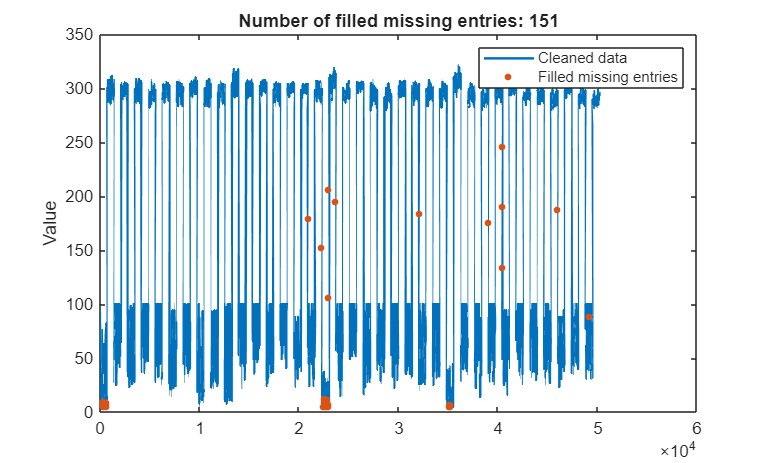

summary(cleanData);

Clean remaining variables by removing the missing data

cleanData = rmmissing(cleanData);


cleanData: 50193×7 table

Variables:

    datetime: datetime (datetime)
    city: string (Data indicator)
    Value: double (Vancouver)
    Variable: cell array of character vectors
    country: cell array of character vectors
    latitude: double
    longitude: double

Statistics for applicable variables:

                 NumMissing              Min                      Median                       Max                       Mean                   Std     

    datetime           9         2017-06-01 00:00:00        2017-06-15 12:00:00        2017-06-30 00:00:00        2017-06-15 12:00:00        201:12:30  
    city               0                                                                                       

summary(cleanData);

## 3. Data Visualization

### Distributions

#### Histograms

figure;


cleanData: 37638×7 table

Variables:

    datetime: datetime (datetime)
    city: string (Data indicator)
    Value: double (Vancouver)
    Variable: cell array of character vectors
    country: cell array of character vectors
    latitude: double
    longitude: double

Statistics for applicable variables:

                 NumMissing              Min                      Median                       Max                       Mean                   Std     

    datetime         0           2017-06-01 00:00:00        2017-06-15 12:00:00        2017-06-30 00:00:00        2017-06-15 12:00:00        201:12:32  
    city             0                                                                                         

subplot(1, 2, 1);
histogram(cleanData.Value(cleanData.Variable=="temperature"), 50);
xlabel("Temperature (°F)"); ylabel("Count");
title("Temperature Distribution");

subplot(1, 2, 2);
histogram(cleanData.Value(cleanData.Variable=="humidity"), 50);
xlabel("Humidity (%)"); ylabel("Count");
title("Humidity Distribution");

### Time Series Plot

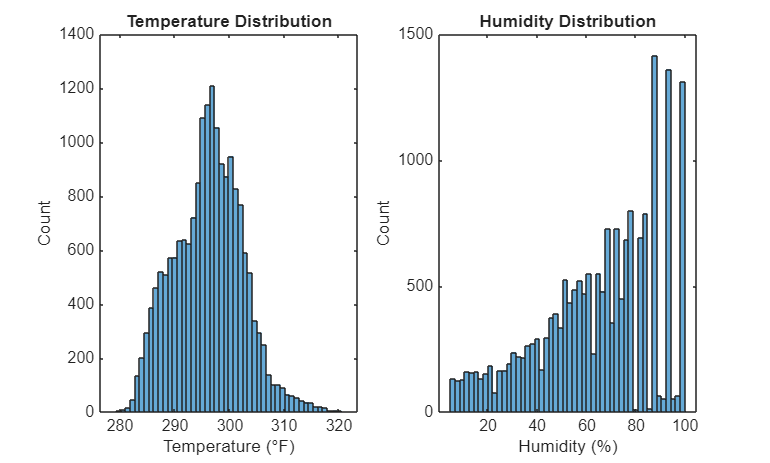

exampleCities = {'Toronto', 'Vancouver'};

figure;
for idx = 1:numel(exampleCities)

    subplot(numel(exampleCities), 1, idx);
    cityData = cleanData(cleanData.city==exampleCities{idx}, :);

    % Temperature
    tempData = cityData(cityData.Variable=="temperature", :);
    plot(tempData.datetime, tempData.Value, 'r');
    hold on;

    % Humidity
    humData = cityData(cityData.Variable=="humidity", :);
    plot(humData.datetime, humData.Value, 'b');

    legend('Temperature', 'Humidity');
    title(['Weather in ', exampleCities{idx}]);
    ylabel('Value');
end
xlabel("Date");
hold off;

#### Map

temperature

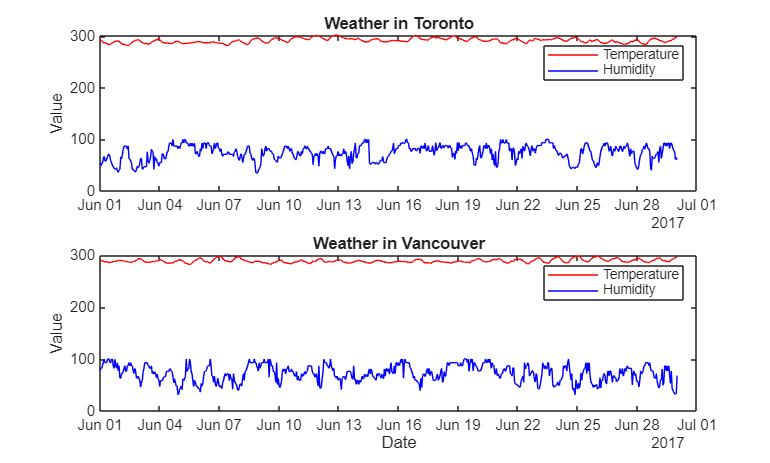

% Filter data
latestDate = max(cleanData.datetime);
latestData = cleanData(cleanData.datetime==latestDate & cleanData.Variable=="temperature", :);


% Read a shapefile containing the coordinates of world cities into the workspace as a geospatial table. Extract the latitude and longitude coordinates.
GT = readgeotable("worldcities.shp");
lat = GT.Shape.Latitude;
lon = GT.Shape.Longitude;

% Specify the projected CRS you want to use. For this example, create a projcrs object for WGS 84 / Equal Earth Asia-Pacific, which has the EPSG code 8859.
equalEarth = projcrs(8859);
wktstring(equalEarth,Format="formatted");

% Specify the latitude and longitude limits for the basemap image by using the information in BBOX. For this projected CRS, unwrap the maximum longitude by adding 360 degrees to the minimum longitude.
latlim = [-90 90];
lonmin = -29.99;
lonlim = [lonmin lonmin+360];

% Read an image from the "satellite" basemap as an array, a map cells reference object in Web Mercator coordinates, and an attribution string.
[A,RA,attrib] = readBasemapImage("satellite",latlim,lonlim);

% Project the geographic coordinates to Equal Earth coordinates.
[xGrid,yGrid] = worldGrid(RA);
[latGrid,lonGrid] = projinv(RA.ProjectedCRS,xGrid,yGrid);
[xEqualEarth,yEqualEarth] = projfwd(equalEarth,latGrid,lonGrid);

% Project the geographic coordinates of the world cities to Equal Earth coordinates. If you are adapting this example to your own code and your data is in projected coordinates, you must first unproject your data to geographic coordinates.
[xData,yData] = projfwd(equalEarth,latestData.latitude, latestData.longitude);

% Display the projected basemap image and world cities on a map with no axis labels.
figure;
mapshow(xEqualEarth,yEqualEarth,A)
hold on
mapshow(xData,yData,DisplayType="point",Marker=".", MarkerSize=10)
title(['Temperature on ', string(latestDate)]);
axis off;

## 4. Modelling and Forecasting

### Regression Learner App

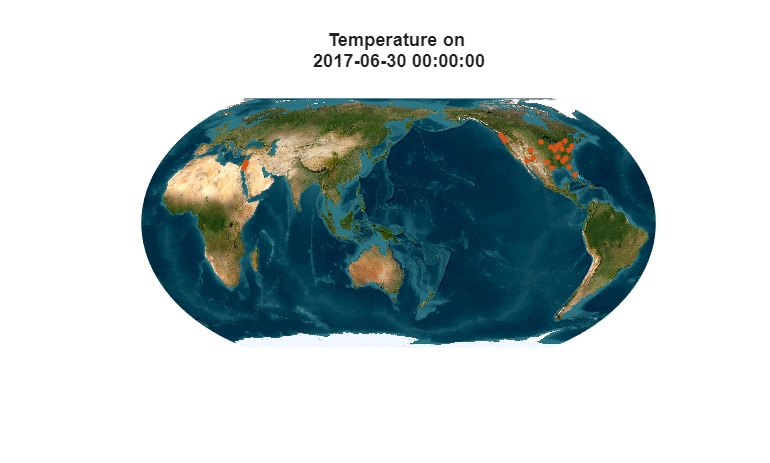

tbl = cleanData(cleanData.Variable=="temperature", :);

% Extract Features
tbl.Hour = hour(tbl.datetime);
tbl.Month = month(tbl.datetime);
tbl.Day = day(tbl.datetime);


% Drop unused colums
tbl = removevars(tbl, ["datetime", "Variable"]);

% Launch Regression Learner App
regressionLearner;

Example Prediction using regression model

tempPrediction = trainedModel.predictFcn(tbl(1:10, :));
% tempPrediction(1:5)
% tbl{1:5, "Value"}

### Econometric Modeler

% Select city
cityName = "Vancouver";
seriesData = cleanData(cleanData.city==cityName & cleanData.Variable=="temperature", :);

% Create timetable
tTbl = timetable(seriesData.datetime, seriesData.Value, 'VariableNames', {'Temperature'});

% Launch econometric modeler app
econometricModeler;

ans =   293.4211
  293.4211
  293.4211
  291.2933
  291.2933


Example forecast using the ARIMA Model

numSteps = 24;

ans =   294.0000
  288.3100
  288.5400
  287.9400
  287.9400


estimatedMdl = estimate(ARMA_Temperature, tTbl.Temperature);
[YF, YMSE] = forecast(estimatedMdl, numSteps, 'Y0', tTbl.Temperature);
futureDates = (tTbl.Time(end) + hours(1:numSteps))';


 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue
                _______    _____________    __________    ______

    Constant     18.382          0             Inf          0   
    Variance    0.83645          0             Inf          0   



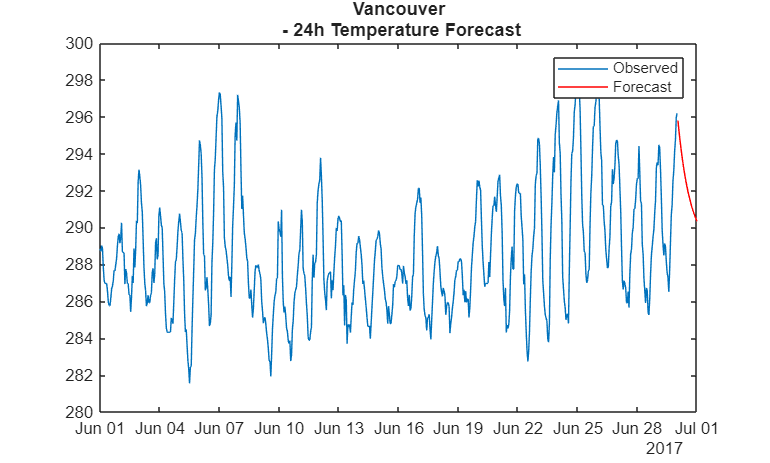

% Plot
figure;
plot(tTbl.Time, tTbl.Temperature(:));
hold on;
plot(futureDates, YF, 'r');
legend('Observed', 'Forecast');
title([cityName ' - 24h Temperature Forecast'])